# Assignment5

## QS1

sys = zpk(-1, [0, -2, -3], 1)

sys =
 
      (s+1)
  -------------
  s (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



pole(sys)

ans =      0
    -2
    -3


zero(sys)

ans = -1

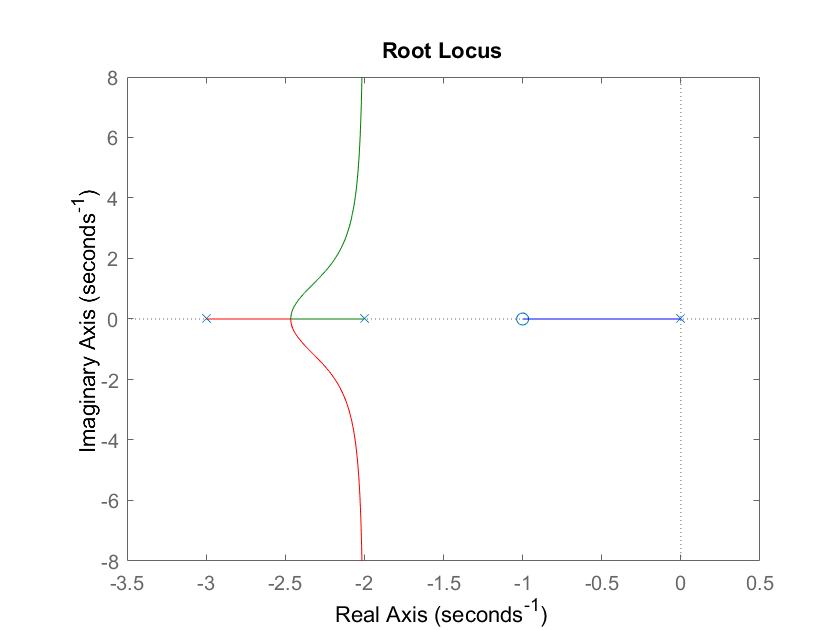

figure;

rlocus(sys)

## QS2

sys = zpk([], [0, -2, -1+1i, -1-1i], 1)

sys =
 
            1
  ----------------------
  s (s+2) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



pole(sys)

ans =    0.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


zero(sys)


ans =

  0×1 empty double column vector



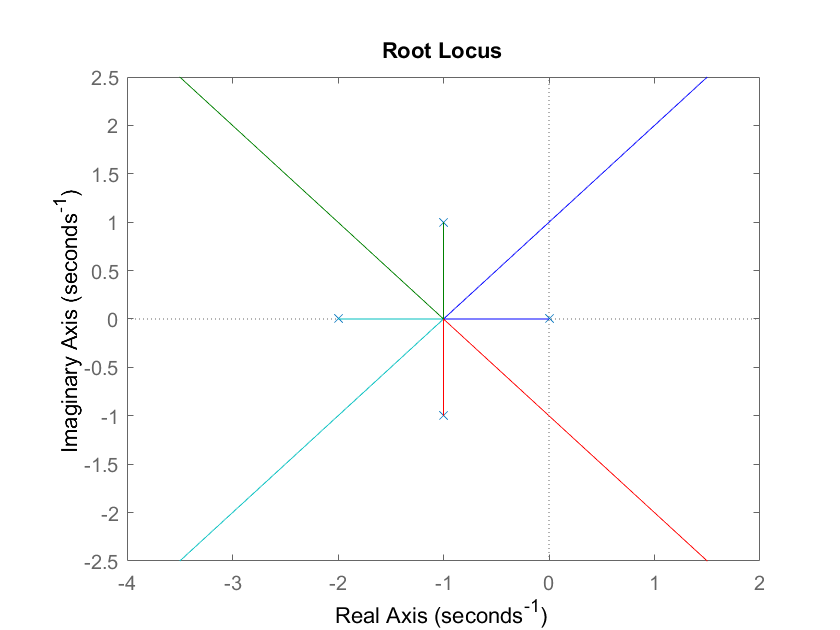

figure;
rlocus(sys)

## QS3

sys = zpk(-1, [0, -4, -1+1i, -1-1i], 1)

sys =
 
          (s+1)
  ----------------------
  s (s+4) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



pole(sys)

ans =    0.0000 + 0.0000i
  -4.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


zero(sys)

ans = -1

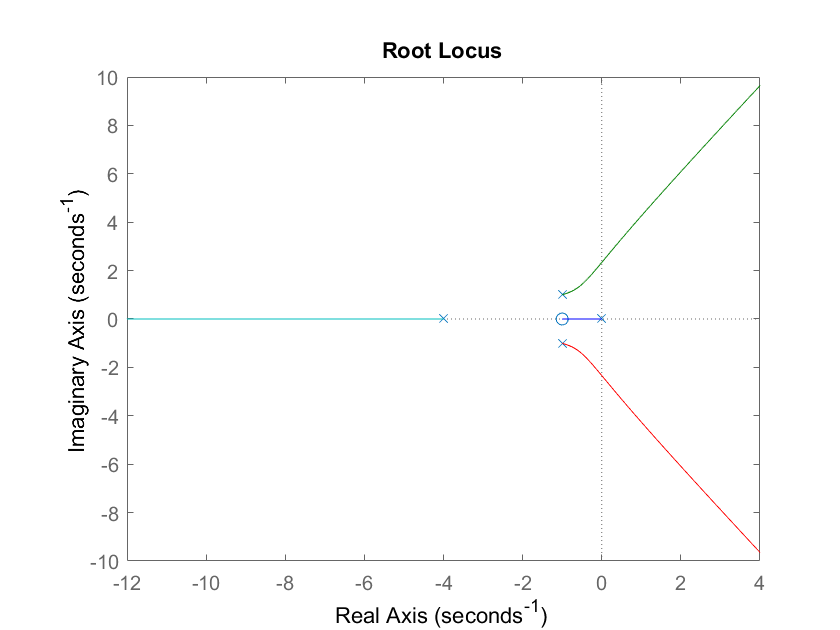

rlocus(sys)

## QS4

sys = zpk([], [0, -3, -1+1i, -1-1i], 1)

sys =
 
            1
  ----------------------
  s (s+3) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



pole(sys)

ans =    0.0000 + 0.0000i
  -3.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


zero(sys)


ans =

  0×1 empty double column vector



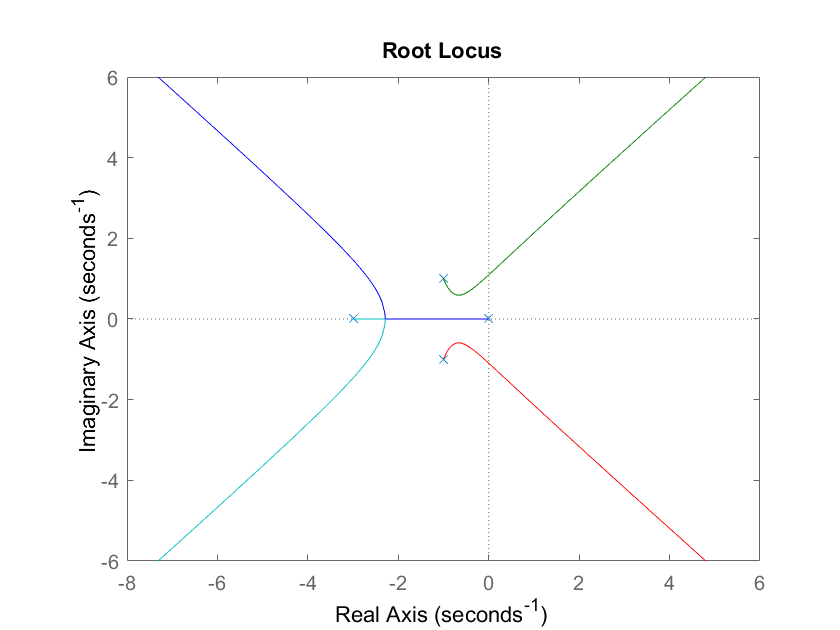

rlocus(sys)

## QS5

sys = zpk([], [0, -4, -2+4i, -2-4i], 1)

sys =
 
             1
  -----------------------
  s (s+4) (s^2 + 4s + 20)
 
Continuous-time zero/pole/gain model.



pole(sys)

ans =    0.0000 + 0.0000i
  -4.0000 + 0.0000i
  -2.0000 + 4.0000i
  -2.0000 - 4.0000i


zero(sys)


ans =

  0×1 empty double column vector



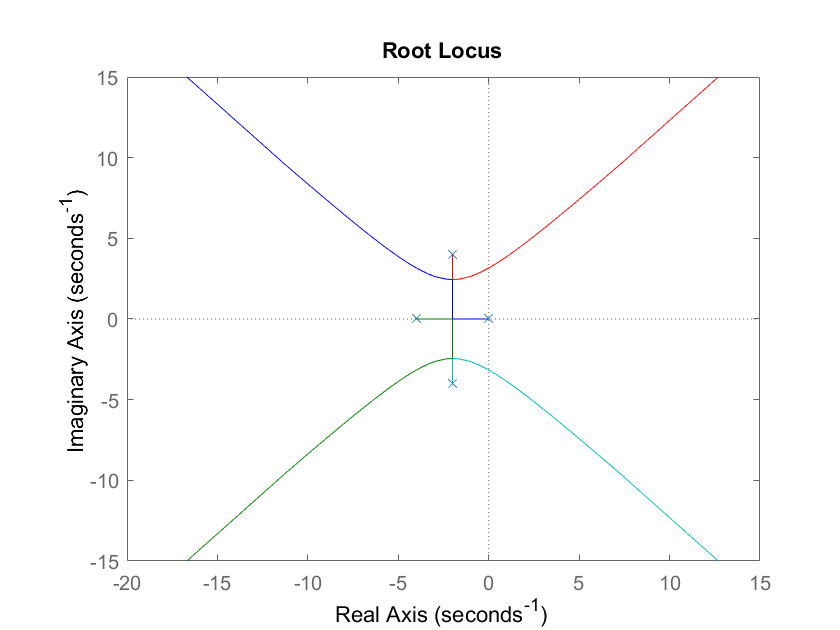

rlocus(sys)

## QS6

sys = zpk(-3, [0, -5, -6, -1+1i, -1-1i], 1)

sys =
 
             (s+3)
  ----------------------------
  s (s+5) (s+6) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



pole(sys)

ans =    0.0000 + 0.0000i
  -5.0000 + 0.0000i
  -6.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


zero(sys)

ans = -3

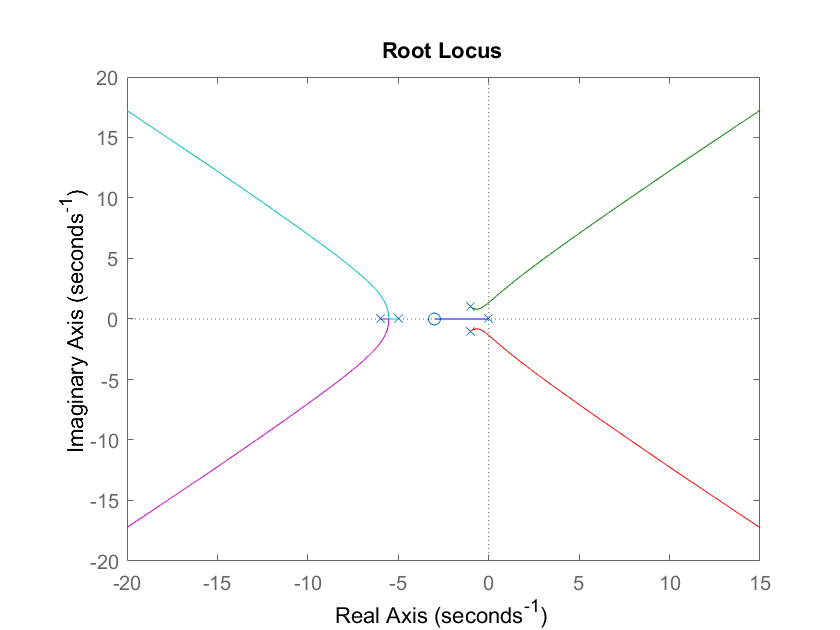

rlocus(sys)

## QS7

sys = zpk(-1, [0, 1, -2+sqrt(3)*2i, -2-sqrt(3)*2i], 1)

sys =
 
           (s+1)
  -----------------------
  s (s-1) (s^2 + 4s + 16)
 
Continuous-time zero/pole/gain model.



pole(sys)

ans =    0.0000 + 0.0000i
   1.0000 + 0.0000i
  -2.0000 + 3.4641i
  -2.0000 - 3.4641i


zero(sys)

ans = -1

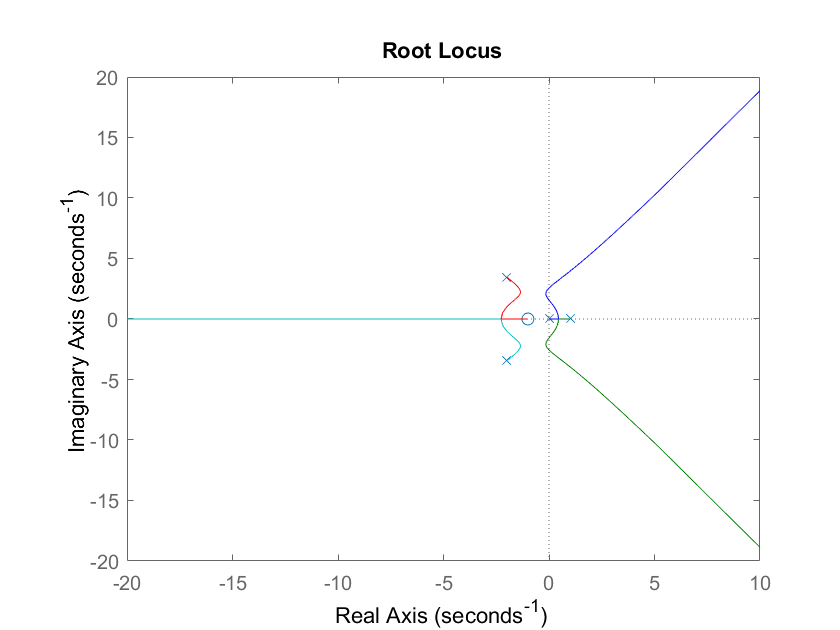

rlocus(sys)

## QS8

% 1
sys1 = tf(1, [1, 6, 45, 0])

sys1 =
 
          1
  ------------------
  s^3 + 6 s^2 + 45 s
 
Continuous-time transfer function.



sys2 = tf([0.075, 1, 1], [1, 3, 5, 0])

sys2 =
 
  0.075 s^2 + s + 1
  -----------------
  s^3 + 3 s^2 + 5 s
 
Continuous-time transfer function.



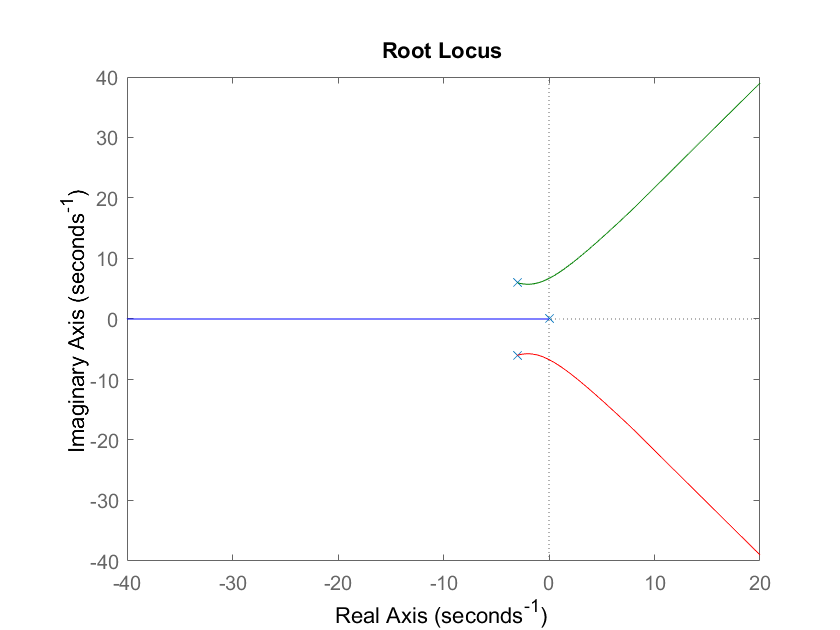

rlocus(sys1)

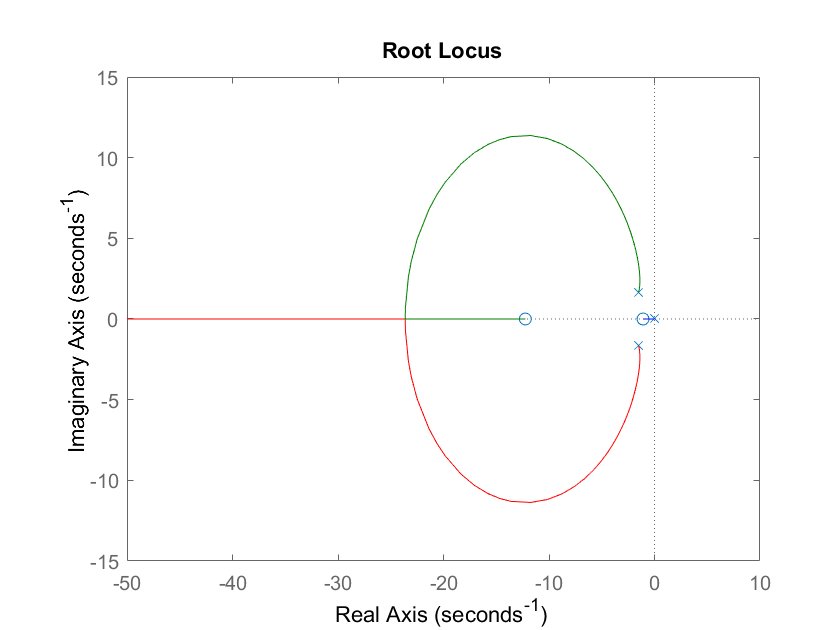

rlocus(sys2)

% 2



% 3
tf1 = tf(1, [1, 6, 45, 0])

tf1 =
 
          1
  ------------------
  s^3 + 6 s^2 + 45 s
 
Continuous-time transfer function.



tf2 = tf([0.075, 1, 1], [1, 3, 5, 0])

tf2 =
 
  0.075 s^2 + s + 1
  -----------------
  s^3 + 3 s^2 + 5 s
 
Continuous-time transfer function.



K = 40;

sys1 = (K* tf1)/(1 + K * tf1) %closed loop

sys1 =
 
               40 s^3 + 240 s^2 + 1800 s
  ----------------------------------------------------
  s^6 + 12 s^5 + 126 s^4 + 580 s^3 + 2265 s^2 + 1800 s
 
Continuous-time transfer function.



sys2 = (K* tf2)/(1 + K * tf2) %closed loop

sys2 =
 
     3 s^5 + 49 s^4 + 175 s^3 + 320 s^2 + 200 s
  ------------------------------------------------
  s^6 + 9 s^5 + 68 s^4 + 205 s^3 + 345 s^2 + 200 s
 
Continuous-time transfer function.



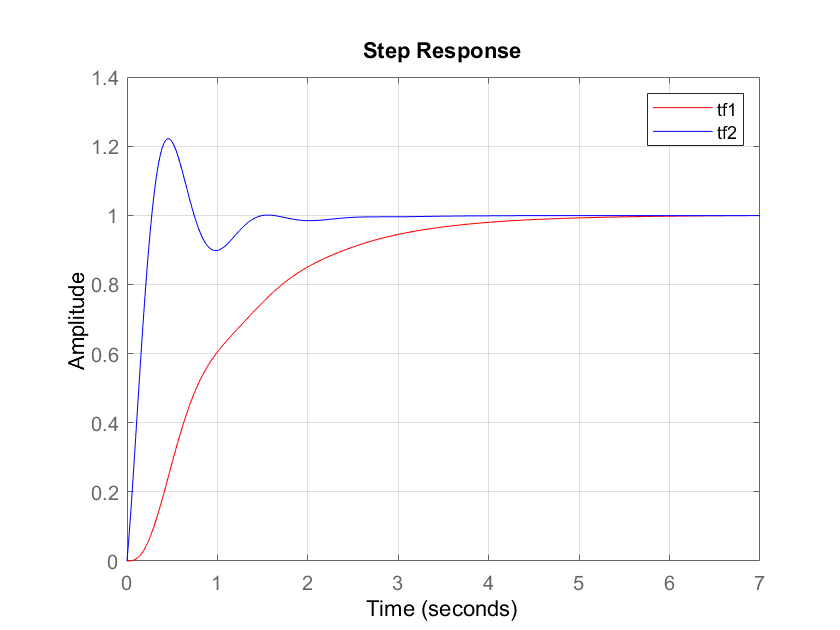

step(sys1, 'r', sys2, 'b')
hold on;
legend('tf1','tf2');
grid on;

info1 = stepinfo(sys1)

info1 = struct with fields:
        RiseTime: 2.1128
    SettlingTime: 4.0172
     SettlingMin: 0.9020
     SettlingMax: 0.9997
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9997
        PeakTime: 8.0683


info2 = stepinfo(sys2)

info2 = struct with fields:
        RiseTime: 0.2085
    SettlingTime: 1.3415
     SettlingMin: 0.8979
     SettlingMax: 1.2217
       Overshoot: 22.1650
      Undershoot: 0
            Peak: 1.2217
        PeakTime: 0.4605


## QS9

sys = tf([1, -2, 2],[1, 5, 6])

sys =
 
  s^2 - 2 s + 2
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.



pole(sys)

ans =    -3.0000
   -2.0000


zero(sys)

ans =    1.0000 + 1.0000i
   1.0000 - 1.0000i


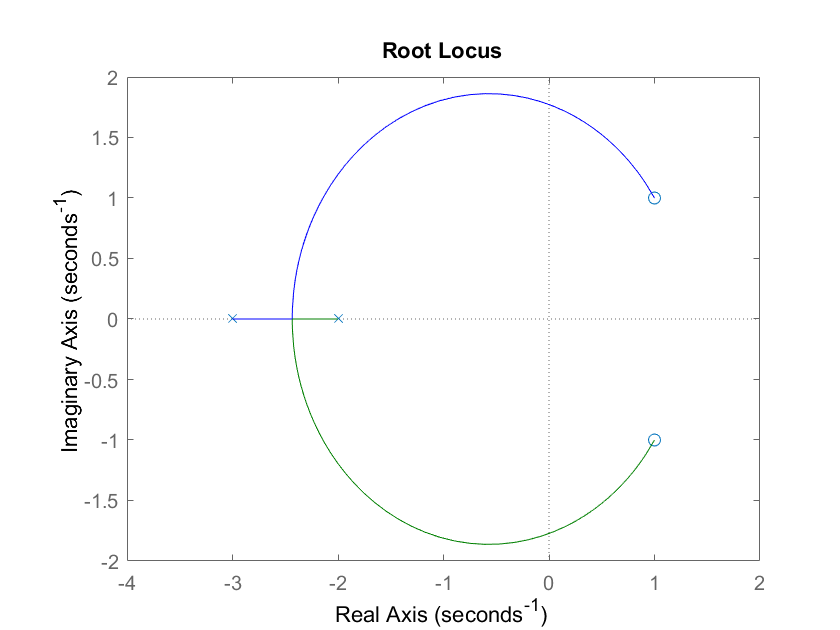

figure
rlocus(sys)

## QS10

% a
sysa = zpk([], [0, -2, -1 + 0.5*1i, -1 - 0.5*1i], 1)

sysa =
 
              1
  -------------------------
  s (s+2) (s^2 + 2s + 1.25)
 
Continuous-time zero/pole/gain model.



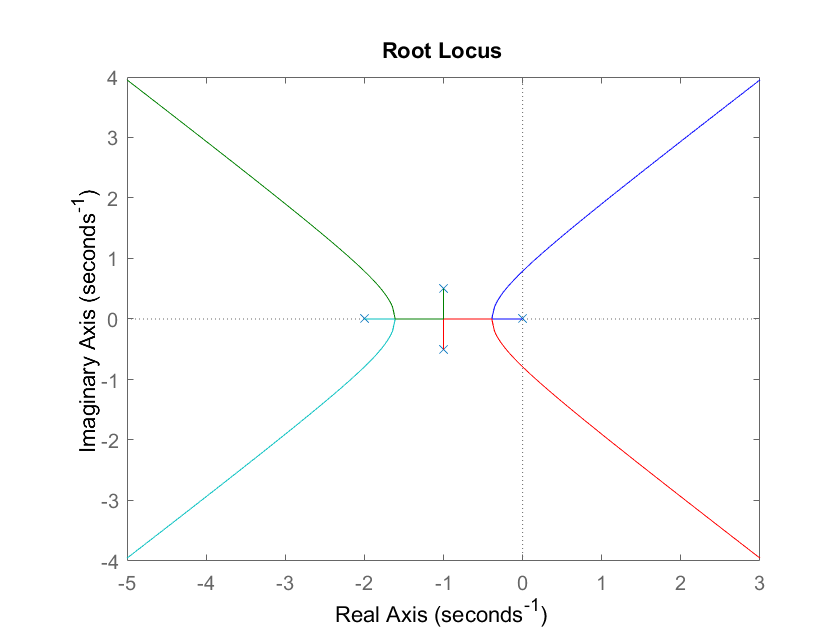

figure
rlocus(sysa)

% b
sysb = zpk([], [0, -2, -1 + 1i, -1 - 1i], 1)

sysb =
 
            1
  ----------------------
  s (s+2) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



rlocus(sysb)

% c
sysc = zpk([], [0, -2, -1 + 3i, -1 - 3i], 1)

sysc =
 
             1
  -----------------------
  s (s+2) (s^2 + 2s + 10)
 
Continuous-time zero/pole/gain model.



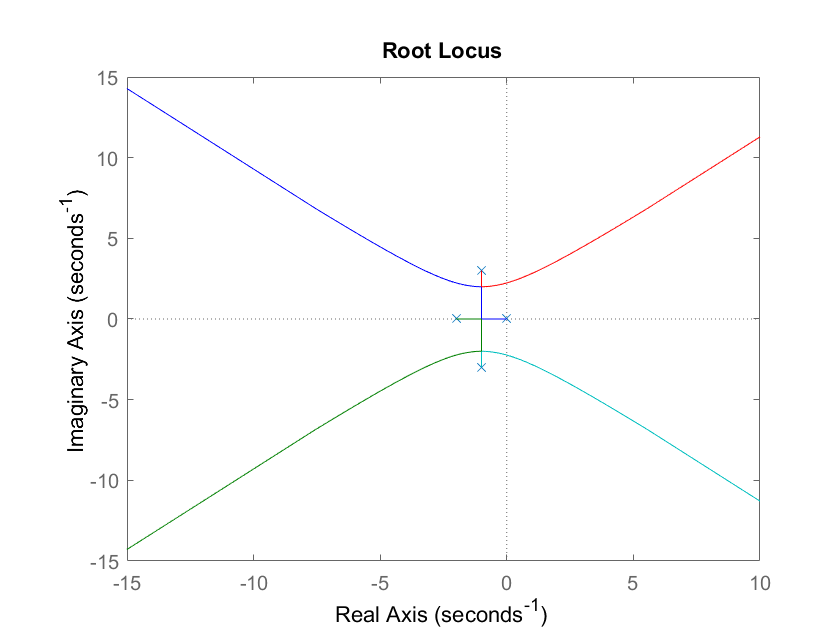

rlocus(sysc)